# **InverseGaussCL**

Inverse lemniscate cosine function

## Definition


$${\mathrm{cl}}^{-1} x=\int_x^1 \frac{\mathit{dt}}{\sqrt{1-t^4 }}$$


([1]).

Domain: $-1<x<1$. For the specified domain, the  codomain is the set of real numbers.

Special values:

   
$${\textrm{cl}}^{-1} \left(1\right)=0$$


Identities:

## Syntax

Y = InverseGaussCL(X)

y = igcl(x)

## Description

**Y = InverseGaussCL(X)** returns the value of the inverse lemniscate cosine function ${\textrm{cl}}^{-1} x$ for each element of the array  X .  X must be real array or scalar. **InverseGaussCL** is the wrapper function which calls the functions **igcl** element-wise via the function **ufun1**.

**y = igcl(x)** returns the value of the inverse lemniscate cosine function ${\textrm{cl}}^{-1} x$ for  x. It is assumed that  x is real scalars without check. y is NaN if x is invalid or convergence failed. **igcl** calculate ${\textrm{cl}}^{-1} x$ by clalling Carlson's fuunction **rf**.

## Precision

## **Numerical Examples**

**Scalar input**

format long
x = 1/2; 
[igcl(x), InverseGaussCL(x)]

ans =    0.807819333968729   0.807819333968729


Accuracy. 

fprintf('%.16g\n',igcl(1/2)) 

0.8078193339687291


% Maple 0.8078193339687290 18

Special values

igcl(1)

ans = 0

Identities

x = pi/4;
disp(igcl(gcl(x))-x)

     1.110223024625157e-16



disp(gcl(igcl(x))-x)

    -3.330669073875470e-16



**Vector input**

x=[1e-6 0.2 -0.3 -1e-20];
disp(GaussCL(InverseGaussCL(x))-x)

   1.0e-15 *

  -0.447937068771202  -0.111022302462516  -0.388578058618805  -0.319532620131762



**Matrix input**

x=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(GaussCL(InverseGaussCL(x))-x)

   1.0e-15 *

  -0.666133814775094  -0.222044604925031  -0.249800180540660
                   0  -0.444089209850063  -0.166533453693773



## **Plot**

**Example 1**

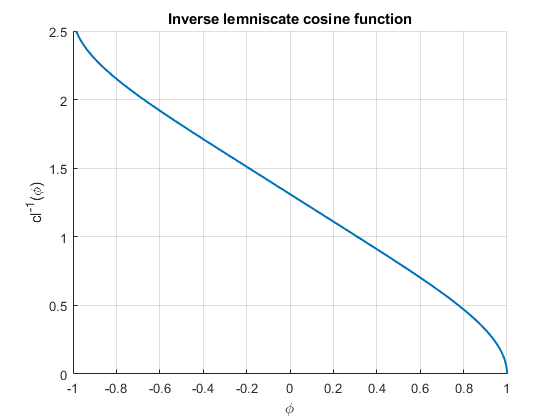

figure
hold on
fplot(@(x) InverseGaussCL(x),'LineWidth',1.5)
title('Inverse lemniscate cosine function')
xlabel('\phi')
ylabel('cl^{-1}(\phi)')
grid on

**Example 2**

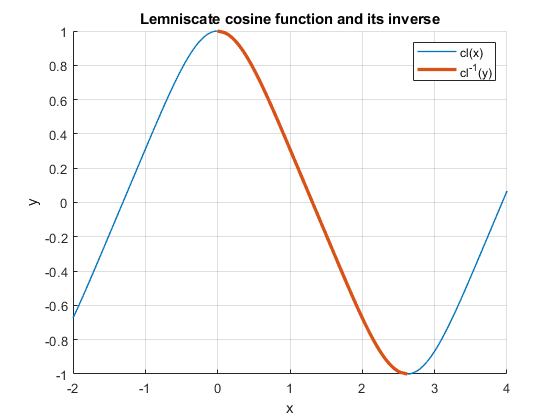

figure
hold on
x=-2:0.01:4;
plot(x,GaussCL(x),'LineWidth',1)
plot(InverseGaussCL(x),x,'LineWidth',2.5)
title('Lemniscate cosine function and its inverse')
legend('cl(x)','cl^{-1}(y)')
xlabel('x')
ylabel('y')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Lemniscatic elliptic function, Wikipedia](https://en.wikipedia.org/wiki/Lemniscatic_elliptic_function)

[Lemniscate functions, Encyclopedia of Mathematics](https://www.encyclopediaofmath.org/index.php/Lemniscate_functions)

## **References**

[1] E.T. Whittaker, G.N. Watson, A course of modern analysis, 4. ed., Cambridge Univ. Pr., Cambridge, 1996.

[2]  [W.Ehrhardt, The AMath and DMath Special functions, 2016](http://www.wolfgang-ehrhardt.de/specialfunctions.pdf)

## See Also